Reducción de orden

clf
syms G(s)
syms k

G  = 0.2*s*(s+2.1)/((s+0.5)*(s+1)*(s+1.9)*(s^2+2*s+2))

$$G = \frac{s\,\left(s+\frac{21}{10}\right)}{5\,\left(s+1\right)\,\left(s+\frac{1}{2}\right)\,\left(s+\frac{19}{10}\right)\,\left(s^{2}+2\,s+2\right)}$$


Gbar = 0.2*s/((s+0.5)*(s+1)*(s^2+2*s+2)) * k

$$Gbar = \frac{k\,s}{5\,\left(s+1\right)\,\left(s+\frac{1}{2}\right)\,\left(s^{2}+2\,s+2\right)}$$


f = subs(Gbar,s,0) == subs(G,s,0);

kvalue = solve(f,k); 

Gbar = subs(Gbar,k,kvalue)

$$Gbar = \frac{s}{5\,\left(s+1\right)\,\left(s+\frac{1}{2}\right)\,\left(s^{2}+2\,s+2\right)}$$


g = zpk([0 -2.1],[-0.5 -1 -1.9 -1+i -1-i],0.2)

g =
 
             0.2 s (s+2.1)
  ------------------------------------
  (s+0.5) (s+1) (s+1.9) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.




gbar = zpk([0],[-0.5 -1 -1+i -1-i],0.2)

gbar =
 
             0.2 s
  ----------------------------
  (s+0.5) (s+1) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



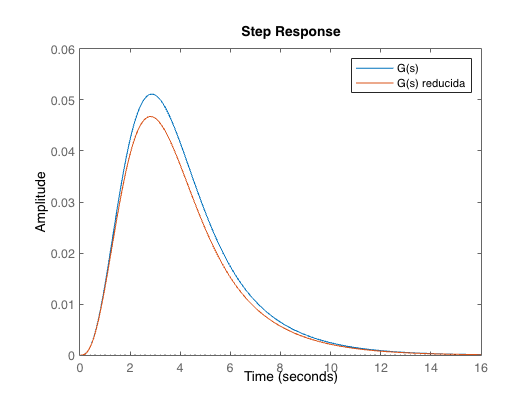


step(g,gbar)
legend("G(s)","G(s) reducida")

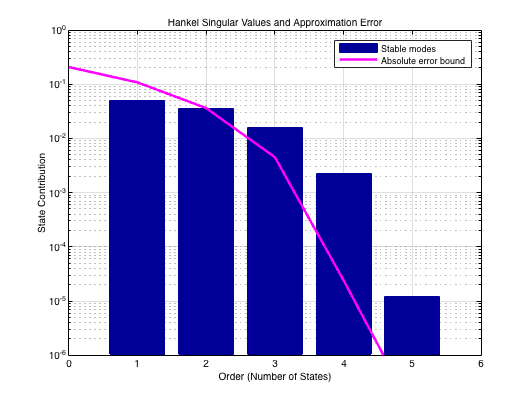


balred(g)


[aproxg,info] = balred(g,1);
aproxg

aproxg =
 
  -0.099152 s
  -----------
   (s+27.46)
 
Continuous-time zero/pole/gain model.



Respuesta temporal original

clf
syms tao
syms G(s) t

G  = 0.2*s*(s+2.1)/((s+0.5)*(s+1)*(s+1.9)*(s^2+2*s+2));

G = partfrac(G);

g = ilaplace(G)

$$g = \frac{22\,{\mathrm{e}}^{-t}}{45}-\frac{32\,{\mathrm{e}}^{-\frac{t}{2}}}{175}-\frac{380\,{\mathrm{e}}^{-\frac{19\,t}{10}}}{11403}-\frac{1234\,{\mathrm{e}}^{-t}\,\left(\cos\left(t\right)-\frac{139\,\sin\left(t\right)}{617}\right)}{4525}$$

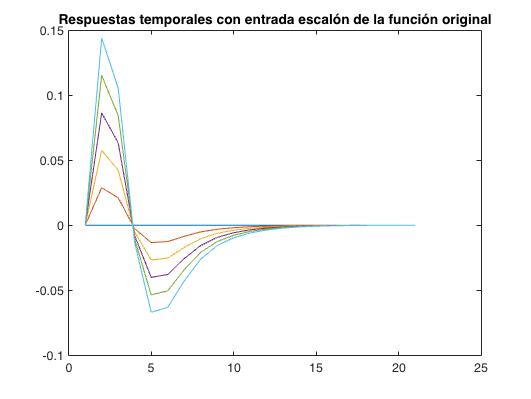

$$a = 0$$

$$a = \frac{22\,{\mathrm{e}}^{-t}}{45}-\frac{32\,{\mathrm{e}}^{-\frac{t}{2}}}{175}-\frac{380\,{\mathrm{e}}^{-\frac{19\,t}{10}}}{11403}-\frac{1234\,{\mathrm{e}}^{-t}\,\left(\cos\left(t\right)-\frac{139\,\sin\left(t\right)}{617}\right)}{4525}$$

$$a = \frac{44\,{\mathrm{e}}^{-t}}{45}-\frac{64\,{\mathrm{e}}^{-\frac{t}{2}}}{175}-\frac{760\,{\mathrm{e}}^{-\frac{19\,t}{10}}}{11403}-\frac{2468\,{\mathrm{e}}^{-t}\,\left(\cos\left(t\right)-\frac{139\,\sin\left(t\right)}{617}\right)}{4525}$$

$$a = \frac{22\,{\mathrm{e}}^{-t}}{15}-\frac{96\,{\mathrm{e}}^{-\frac{t}{2}}}{175}-\frac{380\,{\mathrm{e}}^{-\frac{19\,t}{10}}}{3801}-\frac{3702\,{\mathrm{e}}^{-t}\,\left(\cos\left(t\right)-\frac{139\,\sin\left(t\right)}{617}\right)}{4525}$$

$$a = \frac{88\,{\mathrm{e}}^{-t}}{45}-\frac{128\,{\mathrm{e}}^{-\frac{t}{2}}}{175}-\frac{1520\,{\mathrm{e}}^{-\frac{19\,t}{10}}}{11403}-\frac{4936\,{\mathrm{e}}^{-t}\,\left(\cos\left(t\right)-\frac{139\,\sin\left(t\right)}{617}\right)}{4525}$$

$$a = \frac{22\,{\mathrm{e}}^{-t}}{9}-\frac{32\,{\mathrm{e}}^{-\frac{t}{2}}}{35}-\frac{1900\,{\mathrm{e}}^{-\frac{19\,t}{10}}}{11403}-\frac{1234\,{\mathrm{e}}^{-t}\,\left(\cos\left(t\right)-\frac{139\,\sin\left(t\right)}{617}\right)}{905}$$


timestep = 0:1:20;


for time = 0:1:5
    u = heaviside(time-tao);
    a = int(g*u,tao,0,time)
    f = subs(a,t,timestep);
    

    title("Respuestas temporales con entrada escalón de la función original")
    
    plot(f)
    hold on
end

Respuesta temporal reducida

syms tao
syms G(s) t

clf
Gbar = partfrac(Gbar);

gbar = ilaplace(Gbar)

$$gbar = \frac{2\,{\mathrm{e}}^{-t}}{5}-\frac{4\,{\mathrm{e}}^{-\frac{t}{2}}}{25}-\frac{6\,{\mathrm{e}}^{-t}\,\left(\cos\left(t\right)-\frac{\sin\left(t\right)}{3}\right)}{25}$$

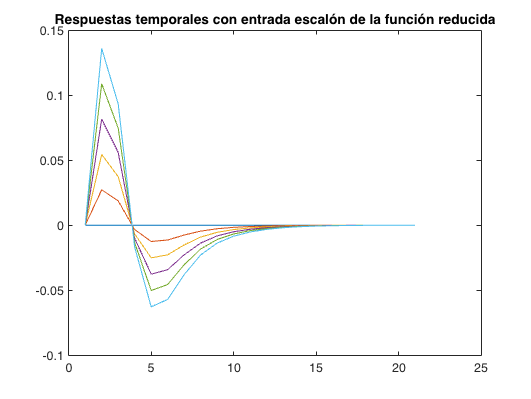

$$a = 0$$

$$a = -\frac{2\,{\mathrm{e}}^{-t}\,\left(2\,{\mathrm{e}}^{t/2}+3\,\cos\left(t\right)-\sin\left(t\right)-5\right)}{25}$$

$$a = -\frac{4\,{\mathrm{e}}^{-t}\,\left(2\,{\mathrm{e}}^{t/2}+3\,\cos\left(t\right)-\sin\left(t\right)-5\right)}{25}$$

$$a = -\frac{6\,{\mathrm{e}}^{-t}\,\left(2\,{\mathrm{e}}^{t/2}+3\,\cos\left(t\right)-\sin\left(t\right)-5\right)}{25}$$

$$a = -\frac{8\,{\mathrm{e}}^{-t}\,\left(2\,{\mathrm{e}}^{t/2}+3\,\cos\left(t\right)-\sin\left(t\right)-5\right)}{25}$$

$$a = -\frac{2\,{\mathrm{e}}^{-t}\,\left(2\,{\mathrm{e}}^{t/2}+3\,\cos\left(t\right)-\sin\left(t\right)-5\right)}{5}$$


timestep = 0:1:20;

for time = 0:1:5 
    u = heaviside(time-tao);
    a = int(gbar*u,tao,0,time)
    f = subs(a,t,timestep);

    title("Respuestas temporales con entrada escalón de la función reducida")

    plot(f)
    hold on
end

clf
clear
%funcion de ponderacion
%respuesta al impulso
syms G(z) k;
syms n;
syms h(k);
G = 0.1*(z-0.7)/((z-0.3)*(z+0.4)^2)
G = partfrac(G)
g = iztrans(G)


g = 20/49 * (-2)^(n-1) * 5^(-n)*heaviside(n-1) + 55/14 * (-2)^(n-2)*5^(-n)*(n-1)*heaviside(n-1)-40/49 * 3^(n-1) * 10^(-n) *heaviside(n-1) 

k = [0 1 2 3 4 5 6 7];

geval = subs(g,n,k);
geval(1) = 0;

geval


G = zpk([0.7],[-0.4 -0.4 0.3], 0.1, 1)



impulse(G)
hold on
plot(geval)
legend("Respuesta al impulso","Secuencia de ponderación")

clf 

g = 20/49 * (-2)^(n-1) * 5^(-n)*heaviside(n-1) + 55/14 * (-2)^(n-2)*5^(-n)*(n-1)*heaviside(n-1)-40/49 * 3^(n-1) * 10^(-n) *heaviside(n-1) 


u=1;
arr = [0];
answ = [0];
answ(1) = 0;
answ(2) = 0;
sol = 0;
grad = 0;
for j = 2:1:5
        sol = sol + subs(g, n, j)
        answ(j+1) = sol;
end

clf

answ

plot(answ,'o')
hold on
step(G)
legend("Respuesta temporal","Step")


syms G(z) k;
syms n;
syms h(k);

G = (z+0.6)/(z^3*(z-0.4)^2)
G =partfrac(G)

g = iztrans(G);

g = 3125/8 * 2^(n-2) * 5^(-n) * (n-1) * heaviside(n-1) - 8125/16 * 2^(n-1) * 5^(-n)* heaviside(n-1)  +1625/16 * kroneckerDelta(n-1) + 25* kroneckerDelta(n-2)+ 15/4* kroneckerDelta(n-3)


G = zpk([-0.6],[0 0 0 0.4 0.4],1,1)
time = 0:1:50;

f = subs(g,n,time);

f(1) = 0;
f(2) = 0;
f(3) = 0;
f(4) = 0;

f
clf
plot(f,'o')
hold
impulse(G)
legend("Secuencia de ponderación","Impulse")


u=1;

answ = [0];
answ(1) = 0;
answ(2) = 0;
sol = 0;
grad = 0;
for j = 3:1:10
        sol = sol + subs(g, n, j);
        answ(j+1) = sol;
end
clf
plot(answ,'o')
hold on
step(G)

answ 
legend("Respuesta temporal","Step")

clf
time = 0:1:100;
u = ones(size(time));
lsim(G,u,time)


syms P X1 X2 X3
A = sym([-1 0 -1; 4 -4 -4; -1 1 -1])

B = [0; 1; 1]

X0 = [1;0;1]

[vec val ] = eig(A);
lam = val(1,1);

f = (A - lam*eye(3)) * [X1; X2; X3] == vec;

[x1 x2 x3]  = solve(f,X1,X2,X3);

P = [x1; x2;x3]

f = (A - lam*eye(3)) * [X1; X2; X3] == P;

[x1 x2 x3]  = solve(f,X1,X2,X3);

Q = [x1; x2;x3]


syms G(z) k;
syms n;
syms h(k);

G = (z+0.6)/(z^3*(z-0.4)^2)
G =partfrac(G)

g = iztrans(G);

g = 3125/8 * 2^(n-2) * 5^(-n) * (n-1) * heaviside(n-1) - 8125/16 * 2^(n-1) * 5^(-n)* heaviside(n-1)  +1625/16 * kroneckerDelta(n-1) + 25* kroneckerDelta(n-2)+ 15/4* kroneckerDelta(n-3)


G = zpk([-0.6],[0 0 0 0.4 0.4],1,1)
time = 0:1:50;

f = subs(g,n,time);

f(1) = 0;
f(2) = 0;
f(3) = 0;
f(4) = 0;

f
clf
plot(f,'o')
hold
impulse(G)
legend("Secuencia de ponderación","Impulse")


u=1;

answ = [0];
answ(1) = 0;
answ(2) = 0;
sol = 0;
grad = 0;
for j = 3:1:10
        sol = sol + subs(g, n, j);
        answ(j+1) = sol;
end
clf
plot(answ,'o')
hold on
step(G)

answ 
legend("Respuesta temporal","Step")

clf
time = 0:1:100;
u = ones(size(time));
lsim(G,u,time)


syms P X1 X2 X3 C1 C2 C3
A = sym([-1 0 -1; 4 -4 -4; -1 1 -1])

B = [0; 1; 1]

X0 = [1;0;1]

[vec val ] = eig(A);
lam = val(1,1);

f = (A - lam*eye(3)) * [X1; X2; X3] == vec;

[x1 x2 x3]  = solve(f,X1,X2,X3);

P = [x1; x2;x3]

f = (A - lam*eye(3)) * [X1; X2; X3] == P;

[x1 x2 x3]  = solve(f,X1,X2,X3);

Q = [x1; x2;x3]

X = C1 * vec * exp(lam*t) + C2 * P * exp(lam*t)+ C3 * Q * exp(lam*t)

x0 = subs(X,t,0) == X0;

[c1 c2 c3] = solve(x0,C1,C2,C3)

X = subs(X,C1,c1);
X = subs(X,C2,c2);
X = subs(X,C3,c3)





syms t s c_1 c_2 c_3
A=sym([-1 0 -1; 4 -4 -4; -1 1 -1])
eigenvec = [vec P Q];



psi = eigenvec*exp(lam*t)

phi = psi * inv(subs(psi,t,0))

invphi = inv(phi)

phi0 = subs(phi,t,0)


syms c1 c2 c3;
syms t;
x = sym([-7 3 6; 2 -3 -2; -5 3 4]);
A = [[-7 3 6]
    [2 -3 -2]
    [-5 3 4]];
G = ss(A,[0;1;1],zeros(size(A)),0);
[vec vals] = eig(x)
fund = [vec(:,1)*exp(vals(1,1)*t) vec(:,2)*exp(vals(2,2)*t) vec(:,3)*exp(vals(3,3)*t) ]
psi = fund*inv(subs(fund,t,0))
F = 0;
y = c1*fund(:,1) +c2*fund(:,2) +c3*fund(:,3);
y = subs(y,t,0)==[1;0;1];
solve(y,c1,c2, c3)
time = 0:1:10;
u = zeros(size(time));
lsim(G,u,time,[1;0;1]);
